m=300;
C_d=1;
A=1.2;
rho=1.225;
C_df=1.5;
mu=1.4;
r_w=0.25;
L=1.6;
h=0.25;
l_f=0.96;
g=9.81;
P_max=124000;
weight_rear=(l_f)/L;
drivetrain_efficiency=0.9;

motor_rpm=[0 1000 2000 3320 4000 5000 6000 6500];
motor_torque=[230 230 230 230 191 153 127 117];

spa=[
    0,  250,   Inf,  0,  -2;   % 1. Start/Finish Straight (Slightly downhill)
    1,  50,    20,   1,   0;   % 2. La Source Hairpin (Right, tight)
    0,  600,   Inf,  0, -15;   % 3. Run down to Eau Rouge (Steep downhill)
    1,  80,    120, -1,   5;   % 4. Eau Rouge (Fast Left, compression, starts climb)
    1,  120,   150,  1,  25;   % 5. Raidillon (Fast Right, massive uphill climb)
    0,  1100,  Inf,  0,  15;   % 6. Kemmel Straight (Continues climbing)
    1,  60,    40,   1,   0;   % 7. Les Combes Part 1 (Right)
    1,  60,    40,  -1,  -2;   % 8. Les Combes Part 2 (Left, starts descent)
    1,  80,    60,   1,  -5;   % 9. Malmedy (Right)
    1,  120,   35,   1, -15;   % 10. Bruxelles / Rivage (Right Hairpin, steep downhill)
    1,  60,    50,  -1,  -5;   % 11. No Name / Speaker's Corner (Left)
    1,  200,   90,  -1, -10;   % 12. Pouhon (Double apex Left, very fast, downhill)
    1,  70,    45,   1,   0;   % 13. Fagnes Part 1 (Right)
    1,  70,    45,  -1,   0;   % 14. Fagnes Part 2 (Left)
    1,  80,    50,   1,  -2;   % 15. Campus (Right)
    1,  100,   80,   1,   2;   % 16. Stavelot (Right, starts the climb back up)
    0,  800,   Inf,  0,   5;   % 17. Run to Blanchimont (Flat out, slight climb)
    1,  250,   220, -1,   2;   % 18. Blanchimont (Flat out Left, massive radius)
    0,  300,   Inf,  0,   0;   % 19. Run to Bus Stop
    1,  80,    25,   1,   0;   % 20. Bus Stop Chicane (Combined Right/Left for simplicity)
];

dx=0.1;
seg_lengths=spa(:,2);
seg_radii=spa(:,3);
seg_z=spa(:,5);
num_segments=size(spa,1);
seg_ends=zeros(num_segments + 1, 1); %seg_ends-Each consecutive element is the end point of the segments defined
seg_ends(2:end)=cumsum(seg_lengths); 
track_length=seg_ends(end);
x_track=0:dx:track_length;
N=length(x_track); %N-Number of points where calculations occur
r_track=zeros(1,N);
grad_track=zeros(1,N);
for i=1:num_segments
    theta=asin(seg_z(i)/seg_lengths(i));
    if i==num_segments
        idx = (x_track>=seg_ends(i))&(x_track<=seg_ends(i+1)); %Logical indexing to get the masking array idx
    else
        idx = (x_track>seg_ends(i))&(x_track<seg_ends(i+1));
    end
    r_track(idx)=seg_radii(i);
    grad_track(idx)=theta;
end
disp(['Track unrolled into ',num2str(N),' data points.']);

Track unrolled into 45301 data points.


v_max=zeros(1,N);
v_limit=((2*P_max)/(rho*C_d*A))^(1/3); %Aerodynamic limit in a straight
disp(['Absolute Aero Top Speed:',num2str(v_limit * 3.6),'km/h']);

Absolute Aero Top Speed:198.921km/h


for i=1:N
    r=r_track(i);
    theta=grad_track(i);
    if isinf(r)
        v_max(i)=v_limit;
    else
        den=1-((mu*rho*C_df*A*r)/(2*m));
        if den<=0
            v_max(i)=v_limit; %If downforce is so high, the speed is not grip limited
        else
            v_max(i) =min(sqrt((mu*g*cos(theta)*r)/den),v_limit); %Just in case the banking is high enough for the maximum corner speed to be greater than the aerodynamic limit
        end
    end
end

%Defining the start point, the point with lowest maximum possible speed
[min_speed,anchor_idx]=min(v_max);
disp(['Slowest point (Anchor) found at index:',num2str(anchor_idx)]);

Slowest point (Anchor) found at index:1


disp(['Minimum apex speed:',num2str(min_speed * 3.6),'km/h']);

Minimum apex speed:0km/h


shift=-(anchor_idx-1);
r_track_shift=circshift(r_track,shift);
grad_track_shift=circshift(grad_track,shift);
v_max_shift=circshift(v_max,shift);

%Gear ratio optimization
gear_sweep=3:0.1:6;
lap_times=zeros(1,length(gear_sweep))

lap_times =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i=1:length(gear_sweep)
    current_gear=gear_sweep(i)
    lap_times(i)=real(simulate_lap(current_gear,r_track,grad_track_shift,v_max_shift,N));
    fprintf('Tested Gear:%.2f|Lap Time:%.3fs\n',current_gear,lap_times(i));
end

current_gear = 3

Tested Gear:3.00|Lap Time:245.122s


current_gear = 3.1000

Tested Gear:3.10|Lap Time:245.101s


current_gear = 3.2000

Tested Gear:3.20|Lap Time:245.102s


current_gear = 3.3000

Tested Gear:3.30|Lap Time:245.150s


current_gear = 3.4000

Tested Gear:3.40|Lap Time:245.187s


current_gear = 3.5000

Tested Gear:3.50|Lap Time:245.244s


current_gear = 3.6000

Tested Gear:3.60|Lap Time:245.258s


current_gear = 3.7000

Tested Gear:3.70|Lap Time:245.314s


current_gear = 3.8000

Tested Gear:3.80|Lap Time:245.801s


current_gear = 3.9000

Tested Gear:3.90|Lap Time:246.637s


current_gear = 4

Tested Gear:4.00|Lap Time:247.608s


current_gear = 4.1000

Tested Gear:4.10|Lap Time:248.657s


current_gear = 4.2000

Tested Gear:4.20|Lap Time:249.795s


current_gear = 4.3000

Tested Gear:4.30|Lap Time:251.003s


current_gear = 4.4000

Tested Gear:4.40|Lap Time:252.270s


current_gear = 4.5000

Tested Gear:4.50|Lap Time:253.590s


current_gear = 4.6000

Tested Gear:4.60|Lap Time:254.953s


current_gear = 4.7000

Tested Gear:4.70|Lap Time:256.353s


current_gear = 4.8000

Tested Gear:4.80|Lap Time:257.786s


current_gear = 4.9000

Tested Gear:4.90|Lap Time:259.248s


current_gear = 5

Tested Gear:5.00|Lap Time:260.732s


current_gear = 5.1000

Tested Gear:5.10|Lap Time:262.246s


current_gear = 5.2000

Tested Gear:5.20|Lap Time:263.778s


current_gear = 5.3000

Tested Gear:5.30|Lap Time:265.328s


current_gear = 5.4000

Tested Gear:5.40|Lap Time:266.895s


current_gear = 5.5000

Tested Gear:5.50|Lap Time:268.478s


current_gear = 5.6000

Tested Gear:5.60|Lap Time:270.074s


current_gear = 5.7000

Tested Gear:5.70|Lap Time:271.685s


current_gear = 5.8000

Tested Gear:5.80|Lap Time:273.307s


current_gear = 5.9000

Tested Gear:5.90|Lap Time:274.940s


current_gear = 6

Tested Gear:6.00|Lap Time:276.585s


[best_time,best_idx]=min(lap_times);
optimal_gear_ratio=gear_sweep(best_idx);
fprintf('\n====================================\n');

fprintf('OPTIMAL GEAR RATIO: %.2f\n', optimal_gear_ratio);

🏆 OPTIMAL GEAR RATIO: 3.10


fprintf('FASTEST LAP TIME:   %.3f seconds\n', best_time);

⏱️ FASTEST LAP TIME:   245.101 seconds


fprintf('====================================\n');

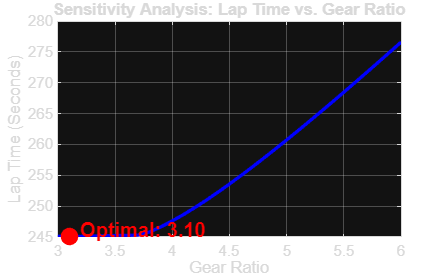

figure('Color', 'w', 'Position', [200, 200, 800, 500]);
plot(gear_sweep, lap_times, 'b-', 'LineWidth', 2);
hold on; grid on;

% Plot a giant red dot exactly at the lowest point
plot(optimal_gear_ratio, best_time, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

% Add a text label pointing to the dot
text(optimal_gear_ratio, best_time + 1, sprintf('  Optimal: %.2f', optimal_gear_ratio), ...
    'FontSize', 12, 'FontWeight', 'bold', 'Color', 'r');

xlabel('Gear Ratio');
ylabel('Lap Time (Seconds)');
title('Sensitivity Analysis: Lap Time vs. Gear Ratio');